# Problem 1

clc;
clear;
close all;
rng('default');

## A) See handwritten part

## B) Generate loglog plots of the Landweber filter function

The behavior of $\phi^{(j)}(\sigma_{i}^{2})$ seems to move to constant value of 1 across values of $\sigma_{i}^{2}$ earlier with increasing values of j, while $\omega$ seems to control the initial starting point of the $\phi^{(j)}(\sigma_{i}^{2})$ curve, with increasing values of $\omega$ starting the $\phi^{(j)}(\sigma_{i}^{2})$ curve at lower values. In general, we can say that $\omega$ seems to control the gain of the Landweber filter, while j controls which eigenvalues get attenuated.

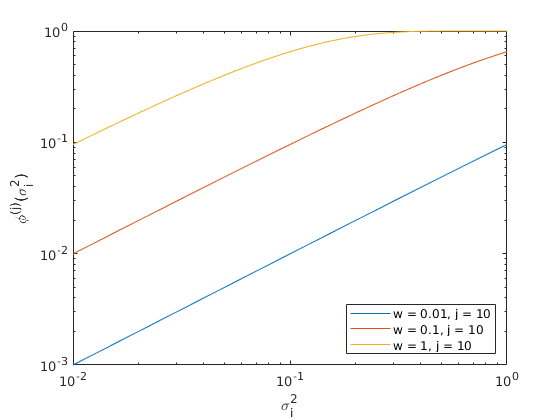

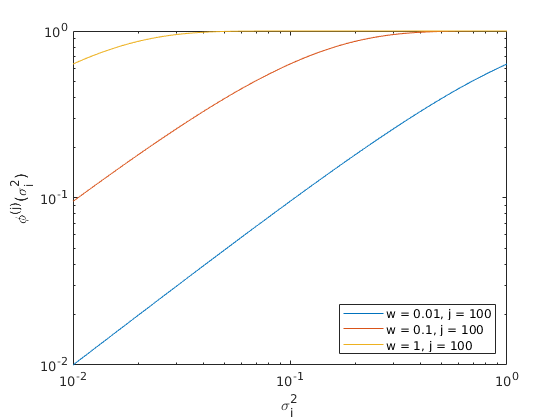

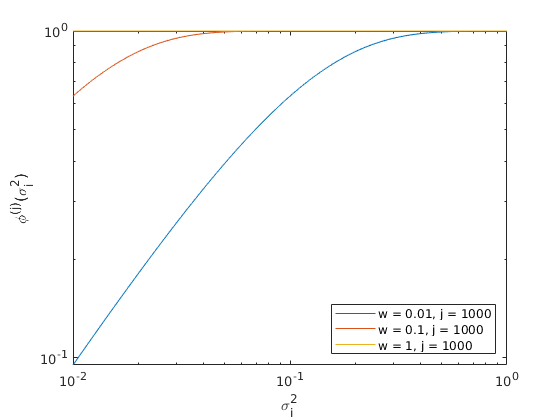

% define the landweber filter function
phi = @(w,j,sigma2) 1 - (1 - w*sigma2).^j;

% define eigenvalues 0 to 1
s2 = logspace(-2,0,100);

% plot for varying w and j
w = [0.01, 0.1, 1];
j = [10, 100, 1000];

% make figure
labels = cell(3,1);
for i=1:numel(j)
    figure;
    for h=1:numel(w)
        loglog(s2,phi(w(h),j(i),s2)); hold on;
        labels{h} = ['\omega = ' num2str(w(h)) ', j = ' num2str(j(i))];
    end
    hold off;
    legend(labels,'Location','southeast');
    xlabel('\sigma_{i}^{2}'); ylabel('\phi^{(j)}(\sigma_{i}^{2})');
end

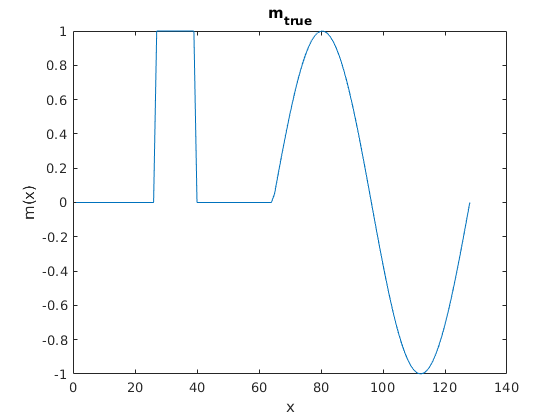

% Number of discretization points
N = 128;
gamma = 0.03;
C = 1 / (sqrt(2*pi)*gamma);

K = zeros(N,N);
h = 1/N;
x = linspace(0,1,N)';

% discrete convolution matrix
for l = 1:N
    for k = 1:N
    	K(l,k) = h * C * exp(-(l-k)^2 * h^2 / (2 * gamma^2));
    end
end

% true image
m_true = (x > .2).*(x < .3) + sin(4*pi*x).*(x > 0.5);
figure; plot(m_true); xlabel('x'); ylabel('m(x)'); title('m_{true}');

% convolved image
d = K * m_true;

## C) Reconstruct m using the Landweber method. Report convergence history

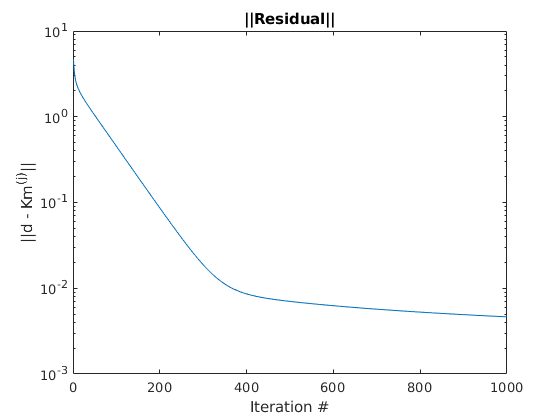

% (i.e. residual and error norms at each iteration)
m_recon = zeros(size(m_true)); % initialize the recon m
iterations = 1000; % set iterations
w = 2; % set step size
residual = zeros(iterations,1); % record euclidean norm
error = zeros(iterations,1); % record error

% run landweber
for i=1:iterations
    m_recon = m_recon + w*K'*(d - K*m_recon);
    residual(i) = norm(d - K*m_recon);
    error(i) = norm(m_true - m_recon);
end

% Plot Residual
figure;
semilogy(residual); title('||Residual||');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

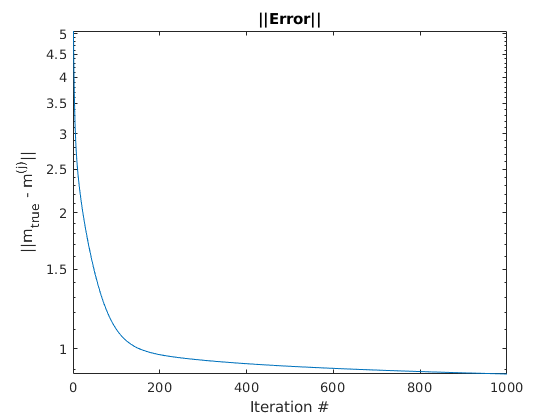

% Plot Error
figure;
semilogy(1:1000,error); title('||Error||');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

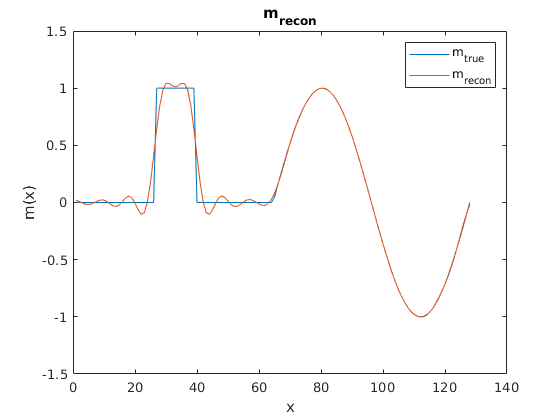

% Plot reconstruction
figure;
plot(m_true); hold on; plot(m_recon);
legend('m_{true}','m_{recon}');
xlabel('x'); ylabel('m(x)'); title('m_{recon}');
hold off;

## D) Add normally distributed noise, and reconstruct m using the Landweber method. Report convergence history

We note that with the addition of noise, the error does not automatically converge to the lowest L2 error with increasing iterations (Error increases after a certain number of iterations). This shows that we must implement a stopping criterion to obtain an optimal result.

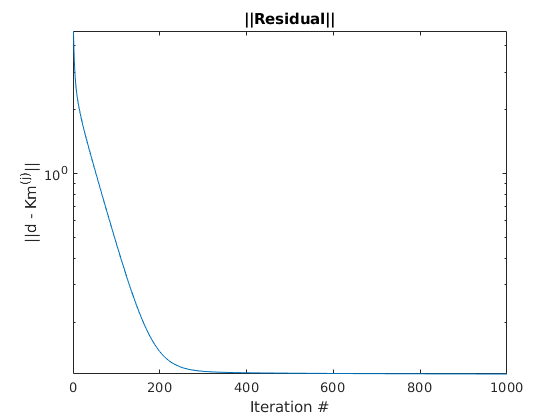

% add noise to data
dn = d + 0.01 * randn(N,1);

% initialize variables
mn_recon = zeros(size(m_true)); % initialize the recon m
iterations = 1000; % set iterations
w = 2; % set step size
residualn = zeros(iterations,1); % record euclidean norm
errorn = zeros(iterations,1); % record error

% run landweber
for i=1:iterations
    mn_recon = mn_recon + w*K'*(dn - K*mn_recon);
    residualn(i) = norm(dn - K*mn_recon);
    errorn(i) = norm(m_true - mn_recon);
end

% Plot Residual
figure;
semilogy(1:1000,residualn); title('||Residual||');
xlabel('Iteration #'); ylabel('||d - Km^{(j)}||');

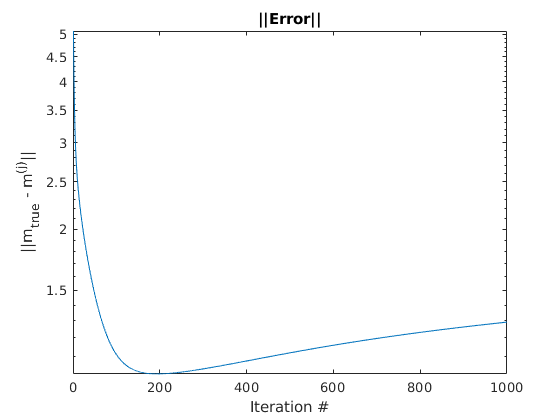

% Plot Error
figure;
semilogy(1:1000,errorn); title('||Error||');
xlabel('Iteration #'); ylabel('||m_{true} - m^{(j)}||');

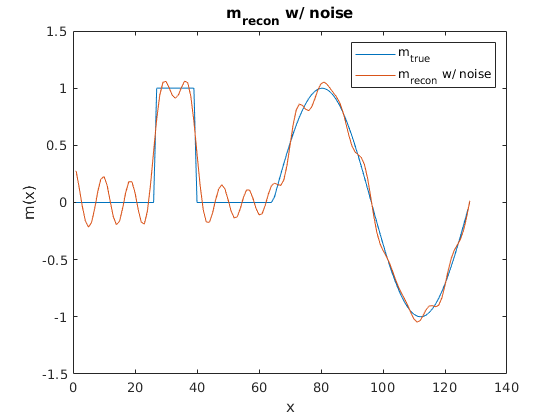

% Plot reconstruction
figure;
plot(m_true); hold on; plot(mn_recon);
legend('m_{true}','m_{recon} w/ noise');
xlabel('x'); ylabel('m(x)'); title('m_{recon} w/ noise');

## E) Use L-curve to find out when to stop.

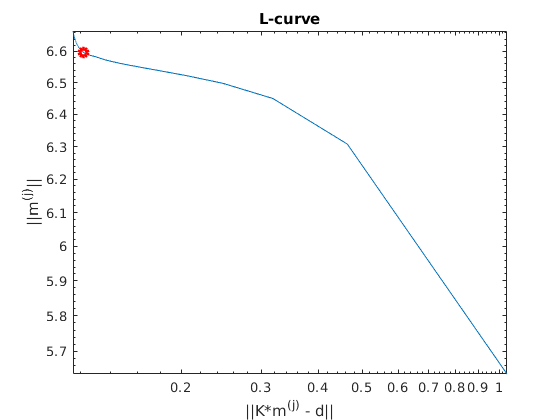

% run L-curve
ml_recon = zeros(size(m_true,1),1000); % initialize the recon m
iterations = 1000; % set iterations
w = 1; % set step size
residuall = zeros(iterations+1,1); % record euclidean norm
normm = zeros(iterations+1,1); % record norm m
for i=1:iterations
    ml_recon(:,i+1) = ml_recon(:,i) + w*K'*(dn - K*ml_recon(:,i));
    residuall(i) = norm(dn - K*ml_recon(:,i+1));
    normm(i) = norm(ml_recon(:,i+1));
end

% plot L-curve
crit = 125; % set index of max curvature
figure; loglog(residuall,normm); hold on;
loglog(residuall(crit),normm(crit), 'ro', 'Linewidth', 3); % circle optimal value
xlabel('||K*m^{(j)} - d||'); ylabel('||m^{(j)}||'); title('L-curve');

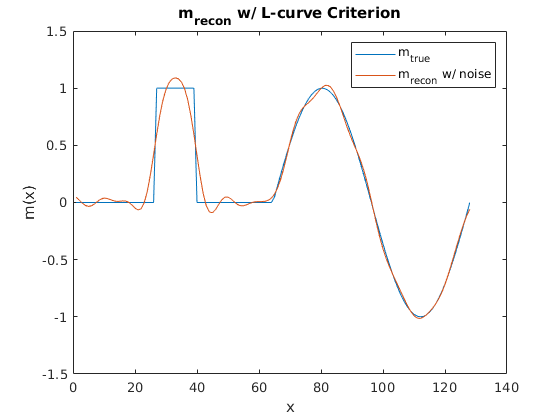

% Plot reconstruction
figure;
plot(m_true); hold on; plot(ml_recon(:,crit));
xlabel('x'); ylabel('m(x)'); title('m_{recon} w/ L-curve Criterion');
legend('m_{true}','m_{recon} w/ noise');
hold off;